# Trajectory - TASK 2

### Robot characteristic

%Definizione delle caratteristiche del robot
clc 
clear all
close all
set(0, 'DefaultFigureRenderer', 'painters');
load_robot_specs



### 1) Trajectory Planning

R = 0.5; dH = 0.1;
P0 = [l0/2 1.1 h-0.1];
v_cost = 0.5;
[s, v, a, dt] = trajectory_planning(R,dH,50,P0,v_cost);


### 1) Kinematics - gripper coordinates 

#### 
$$\dot{Q} = J\dot{S}$$


Calculate the trajectory


$$\dot{J}_s \dot{S} + J_s \ddot{S} + \dot{J} _q \dot{Q}+J_q\ddot{Q}=0$$


for i = 1:1:length(s)

    if i==1
        guess = [130*pi/180 50*pi/180];
    else
        guess = q(i-1,:);
    end
    q(i,:) = inverse_kinematics(s(i,:),L,guess); 
    [J, J_s, J_q] = Jacobian(s(i,:),q(i,:),L);
    qp(i,:) = J*v(i,1:2)';
    qpp(i,:) = -inv(J_q)*((Jp_s(q(i,:),qp(i,:),v(i,1:2),L)*v(i,1:2)'+J_s*a(i,1:2)'+Jp_q(s(i,:),q(i,:),qp(i,:),v(i,1:2),L)*qp(i,:)'));
    
end

tt=dt;
for i=2:length(dt)
    tt(i)=tt(i)+tt(i-1);
end

### 2D Plot

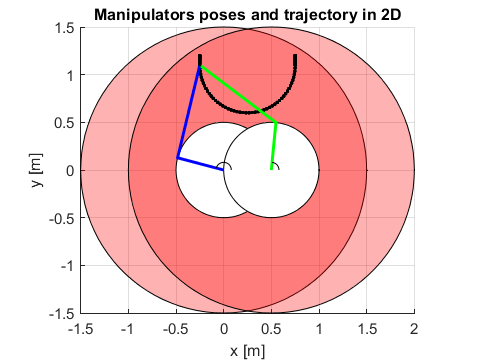

close all

figure(1)
% Plot workspace
center_x = 0; center_y = 0; radius = l1+l2; th = 0:pi/50:2*pi; % radians
coordinates_x = radius*cos(th) + center_x; coordinates_y = radius * sin(th) + center_y;
% Plot the circle
patch(coordinates_x,coordinates_y,'red')
axis square tight 
alpha(0.3)
center_x = l0; center_y = 0; radius = l1+l2; th = 0:pi/50:2*pi; % radians
coordinates_x = radius * cos(th) + center_x; coordinates_y = radius * sin(th) + center_y;
% Plot the circle
patch(coordinates_x,coordinates_y,'red')
axis square tight 
alpha(0.3)

center_x = 0; center_y = 0; radius = l2-l1; th = 0:pi/50:2*pi; % radians
coordinates_x = radius * cos(th) + center_x; coordinates_y = radius * sin(th) + center_y;
patch(coordinates_x,coordinates_y,'white')

center_x = l0; center_y = 0; radius = l2-l1; th = 0:pi/50:2*pi; % radians
coordinates_x = radius * cos(th) + center_x; coordinates_y = radius * sin(th) + center_y;
patch(coordinates_x,coordinates_y,'white')
axis equal
grid on

for i=1:length(s)
    % Print
    [config1, theta(i)] = plot2D_1st(q(i,:),L,1,s(i,1),s(i,2));
    [config2, gamma(i)] = plot2D_2nd(q(i,:),L,1,s(i,1),s(i,2));
    plot(s(i,1),s(i,2),'.-black')
    % Plot the angle arc
    h1 = plotAngleArc([0,0],0.08,[0,q(i,1)],'k-',1); %alfa
    h2 = plotAngleArc([l0,0],0.08,[0,q(i,2)],'k-',1); %beta
    
    pause(dt)
    if i==length(s)
        break
    end
    delete(config1); delete(config2); delete(h1); delete(h2);
    hold off
    title('Manipulators poses and trajectory in 2D');
    xlabel('x [m]')
    ylabel('y [m]')
end

### 3D Plot

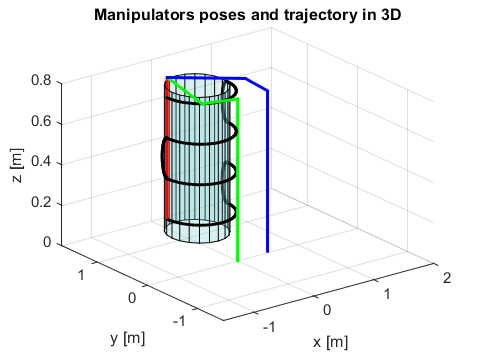

close all
figure(2)


r = 0.42;
[X,Y,Z] = cylinder(r);
Z = Z*(h-0.08);
surf(X+0.25,Y+1.1,Z,'FaceColor', [0.5,0.8,0.8]);
alpha(0.3)
xlim([-l1-l2,l0+l1+l2]);
ylim([-l1-l2,l1+1.2*l2]);
zlim([0,h]);

xlabel('x [m]')
ylabel('y [m]')
zlabel('z [m]')
title('Manipulators poses and trajectory in 3D');
grid on

for i=1:length(s)
    % Print
    [config1, theta(i)] = Plot3D_1st(q(i,:),L,2,s(i,1),s(i,2));
    [config2, gamma(i)] = Plot3D_2nd(q(i,:),L,2,s(i,1),s(i,2));
    config3 = Plot3D_3rd(L,2,s(i,1),s(i,2),s(i,3));
    plot3(s(i,1),s(i,2),s(i,3),'.-black');
    
    pause(dt)
    if i==length(s)
        break
    end
    delete(config1); delete(config2); delete(config3)
end

hold off

### 1a) Print $\alpha ,\beta ,\gamma \;$and $\theta$

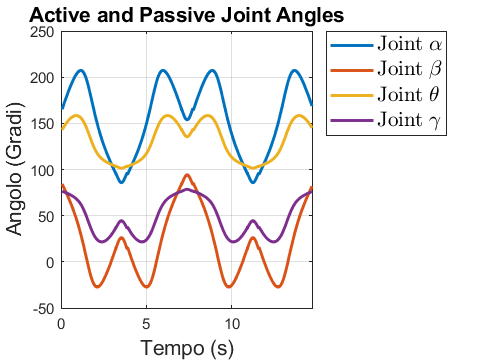

figure(3)
% alpha e beta
plot(tt,q(1:end-1,1)*180/pi,'LineWidth',2); hold on
plot(tt,q(1:end-1,2)*180/pi,'LineWidth',2); hold on
plot(tt,gamma(1:end-1)*180/pi,'LineWidth',2);hold on
plot(tt,theta(1:end-1)*180/pi,'LineWidth',2); hold off
xlim([0,tt(end)]);
title('Active and Passive Joint Angles',FontSize=14);
xlabel('Tempo (s)',FontSize=14);
ylabel('Angolo (Gradi)',FontSize=14);
grid on
h_legend=legend('Joint $\alpha$','Joint $\beta$','Joint $\theta$','Joint $\gamma$');
set(h_legend, 'location', 'northeastoutside')
set(h_legend,'Interpreter','latex');
set(h_legend,'FontSize',14);

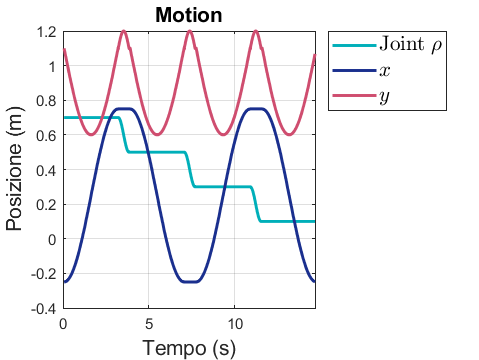



% rho
figure(4)
plot(tt,q(1:end-1,3),'Color',[0, 0.6863, 0.7255],'LineWidth',2); hold on
plot(tt,s(1:end-1,1),'Color',[0.1 0.1840 0.5560],'LineWidth',2); hold on
plot(tt,s(1:end-1,2),'Color',[0.8118, 0.3020, 0.4353],'LineWidth',2); hold off
xlim([0,tt(end)]);
title('Motion',FontSize=14);
xlabel('Tempo (s)',FontSize=14);
ylabel('Posizione (m)',FontSize=14);
grid on
h_legend=legend('Joint $\rho$','$x$','$y$');
set(h_legend, 'location', 'northeastoutside')
set(h_legend,'Interpreter','latex');
set(h_legend,'FontSize',14);

### 1b) Debug

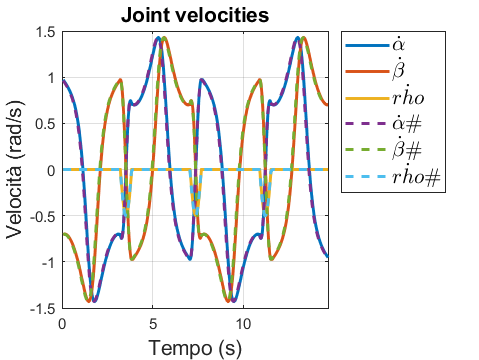


% Joint
for i=2:1:(length(dt)-1)
    if q(i,:)-q(i-1,:) ==0
        qp_alfa_debug(i-1) = qp_alfa_debug(i-2);
        qp_beta_debug(i-1) = qp_beta_debug(i-2);
        qp_rho_debug(i-1) = qp_rho_debug(i-2);

        qpp_alfa_debug(i-1) = qpp_alfa_debug(i-2);
        qpp_beta_debug(i-1) = qpp_beta_debug(i-2);
        qpp_rho_debug(i-1) = qpp_rho_debug(i-2);
    else
        qp_alfa_debug(i-1) = (q(i,1)-q(i-1,1))/dt(i-1);
        qp_beta_debug(i-1) = (q(i,2)-q(i-1,2))/dt(i-1);
        qp_rho_debug(i-1) = (s(i,3)-s(i-1,3))/dt(i-1);

        qpp_alfa_debug(i-1) = (qp(i,1)-qp(i-1,1))/dt(i-1);
        qpp_beta_debug(i-1) = (qp(i,2)-qp(i-1,2))/dt(i-1);
        qpp_rho_debug(i-1) = (v(i,3)-v(i-1,3))/dt(i-1);
    end
end

figure(5)
plot(tt,qp(1:end-1,1),LineWidth=2); hold on
plot(tt,qp(1:end-1,2) ,LineWidth=2); hold on
plot(tt,v(1:end-1,3) ,LineWidth=2); hold on
plot(tt(1:end-2),qp_alfa_debug,"--",LineWidth=2); hold on
plot(tt(1:end-2),qp_beta_debug,"--",LineWidth=2); hold on
plot(tt(1:end-2),qp_rho_debug,"--",LineWidth=2);
xlim([0,tt(end)]);
h_legend=legend('$\dot{\alpha}$','$\dot{\beta}$','$\dot{rho}$','$\dot{\alpha}\#$','$\dot{\beta}\#$','$\dot{rho}\#$');
set(h_legend, 'location', 'northeastoutside')
set(h_legend,'Interpreter','latex');
set(h_legend,'FontSize',14);
title('Joint velocities',FontSize=14);
xlabel('Tempo (s)',FontSize=14)
ylabel('Velocità (rad/s)',FontSize=14)
grid on

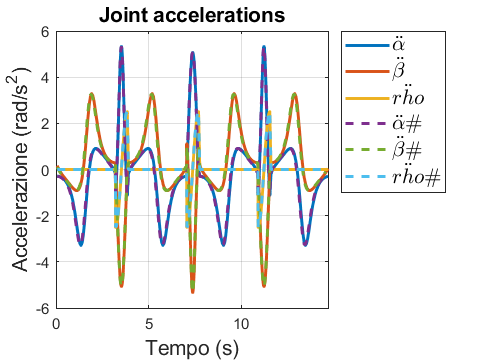


figure(6)
plot(tt,qpp(1:end-1,1),LineWidth=2); hold on
plot(tt,qpp(1:end-1,2) ,LineWidth=2); hold on
plot(tt,a(1:end-1,3) ,LineWidth=2); hold on
plot(tt(1:end-2),qpp_alfa_debug,"--",LineWidth=2); hold on
plot(tt(1:end-2),qpp_beta_debug,"--",LineWidth=2); hold on
plot(tt(1:end-2),qpp_rho_debug,"--",LineWidth=2);
xlim([0,tt(end)]);
h_legend=legend('$\ddot{\alpha}$','$\ddot{\beta}$','$\ddot{rho}$','$\ddot{\alpha}\#$','$\ddot{\beta}\#$','$\ddot{rho}\#$');
set(h_legend, 'location', 'northeastoutside')
set(h_legend,'Interpreter','latex');
set(h_legend,'FontSize',14);
title('Joint accelerations',FontSize=14);
xlabel('Tempo (s)',FontSize=14)
ylabel('Accelerazione (rad/s^2)',FontSize=14)
grid on

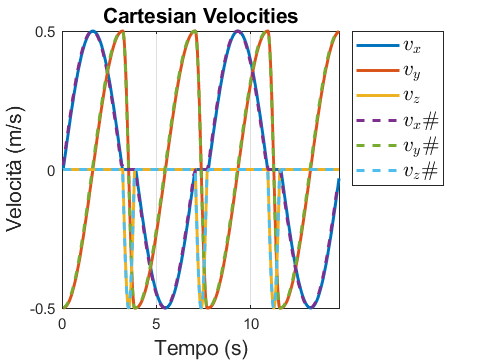


% Cartesian
for i=2:1:(length(dt)-1)
    if s(i,:)-s(i-1,:) == 0
        vx_debug(i-1) = vx_debug(i-2);
        vy_debug(i-1) = vy_debug(i-2);
        vz_debug(i-1) = vz_debug(i-2);
        ax_debug(i-1) = ax_debug(i-2);
        ay_debug(i-1) = ay_debug(i-2);
    else
        vx_debug(i-1) = (s(i,1)-s(i-1,1))/dt(i-1);
        vy_debug(i-1) = (s(i,2)-s(i-1,2))/dt(i-1);
        vz_debug(i-1) = (s(i,3)-s(i-1,3))/dt(i-1);
        ax_debug(i-1) = (v(i,1)-v(i-1,1))/dt(i-1);
        ay_debug(i-1) = (v(i,2)-v(i-1,2))/dt(i-1);
        az_debug(i-1) = (v(i,3)-v(i-1,3))/dt(i-1);
    end
   
end

figure(7)
plot(tt,v(1:end-1,1),LineWidth=2); hold on
plot(tt,v(1:end-1,2),LineWidth=2); hold on
plot(tt,v(1:end-1,3),LineWidth=2); hold on
plot(tt(1:end-2),vx_debug,"--",LineWidth=2); hold on
plot(tt(1:end-2),vy_debug,"--",LineWidth=2); hold on
plot(tt(1:end-2),vz_debug,"--",LineWidth=2);
xlim([0,tt(end)]);
h_legend=legend('$v_x$','$v_y$','$v_z$','$v_x\#$','$v_y\#$','$v_z\#$');
set(h_legend, 'location', 'northeastoutside')
set(h_legend,'Interpreter','latex');
set(h_legend,'FontSize',14);
title('Cartesian Velocities',FontSize=14);
xlabel('Tempo (s)',FontSize=14)
ylabel('Velocità (m/s)',FontSize=14)
grid on

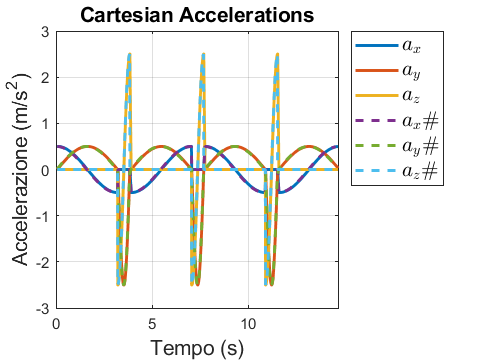


figure(8)
plot(tt,a(1:end-1,1),LineWidth=2); hold on
plot(tt,a(1:end-1,2),LineWidth=2); hold on
plot(tt,a(1:end-1,3),LineWidth=2); hold on
plot(tt(1:end-2),ax_debug ,"--",LineWidth=2); hold on
plot(tt(1:end-2),ay_debug,"--",LineWidth=2); hold on
plot(tt(1:end-2),az_debug,"--",LineWidth=2);
xlim([0,tt(end)]);
h_legend=legend('$a_x$','$a_y$','$a_z$','$a_x\#$','$a_y\#$','$a_z\#$');
set(h_legend, 'location', 'northeastoutside')
set(h_legend,'Interpreter','latex');
set(h_legend,'FontSize',14);
title('Cartesian Accelerations',FontSize=14);
xlabel('Tempo (s)',FontSize=14)
ylabel('Accelerazione (m/s^2)',FontSize=14)
grid on

### 2) Dynamics


$$F_q = ({J_e}^t M J_e)\ddot{Q}+{J_e}^tM\dot{J_e}\dot{Q}-{J_e}^tF_{se}$$


Je_0 = Jacobian_Ext(q(1,1:2),L,G,J);
for i = 2:length(dt)
    if i==2
        Je=Jacobian_Ext(q(i,1:2),L,G,J);
        Jep = (Je-Je_0)./dt(i-1);
    else
        Je_0=Jacobian_Ext(q(i-1,1:2),L,G,J);
        Je=Jacobian_Ext(q(i,1:2),L,G,J);
        Jep = (Je-Je_0)./dt(i-1);
    end
    
    Fq(i,:) = (Je'*M*Je)*qpp(i,1:2)' + (Je'*M*Jep)*qp(i,1:2)'-transpose(Je)*Fse;
    Se=direct_dynamics(q(i,1:2),s(i,:),L,G);
    Sep(:,i) = Je*qp(i,1:2)';
    Ek(i,:) = (1/2)*Sep(:,i)'*M*Sep(:,i);
    Ep(i,:) = transpose(Ag)*M*Se;
    E_tot(i,:) = Ep(i,:) + Ek(i,:);
    W(i,:)=qp(i,1:2)*Fq(i,:)'+Sep(:,i)'*Fse;
    
end


for i=1:length(a)
    Fq(i,3) = m_gripper*(-9.81+a(i,3));
end


### 2a) Actuator torques

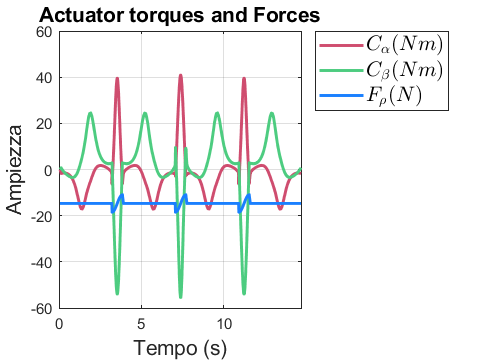

for i = 2:length(dt)
     W_debug(i) = (E_tot(i)-E_tot(i-1))/dt(i);
end

figure(9)
plot(tt,Fq(1:end-1,1),'Color',[0.8118, 0.3020, 0.4353],'LineWidth',2); hold on
plot(tt,Fq(1:end-1,2),'Color',[0.3, 0.8, 0.5],'LineWidth',2); hold on
plot(tt,Fq(1:end-1,3),'Color',[0.1, 0.5, 1],'LineWidth',2);
title("Actuator torques and Forces",FontSize=14)
grid on
ylabel('Ampiezza',FontSize=14)
xlabel('Tempo (s)',FontSize=14)
xlim([0,tt(end)])
h_legend = legend('$C_{\alpha} (Nm)$','$C_{\beta}(Nm)$','$F_{\rho} (N)$');
set(h_legend, 'location', 'northeastoutside')
set(h_legend,'Interpreter','latex');
set(h_legend,'FontSize',14);

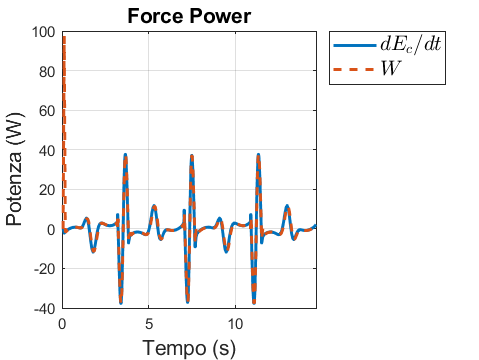


figure(10)
plot(tt,W,LineWidth=2);hold on
plot(tt,W_debug,"--",LineWidth=2);hold off
title("Force Power",FontSize=14)
ylabel('Potenza (W)',FontSize=14)
xlabel('Tempo (s)',FontSize=14)
xlim([0,tt(end)])
h_legend=legend('$dE_c/dt$', '$W$');
set(h_legend, 'location', 'northeastoutside')
set(h_legend,'Interpreter','latex');
set(h_legend,'FontSize',14);
grid on

### Checking velocity and acceleration limits

% Velocity
for i=1:length(qp)
    if (qp(i,1) < vel_limits(1)) && (qp(i,1)>vel_limits(2))
        msgbox('Actuator limit exceeded on alpha')
    end
    if (qp(i,2) < vel_limits(3)) && (qp(i,2)>vel_limits(4))
        msgbox('Actuator limit exceeded on beta')
    end
    if (v(i,3) < vel_limits(5)) && (v(i,3)>vel_limits(6))
        msgbox('Actuator limit exceeded on rho')
    end
end

% Acceleration
for i=1:length(qpp)
    if (qpp(i,1) < -acc_limits(1)) && (qpp(i,1)>acc_limits(2))
        msgbox('Actuator limit exceeded on alpha')
    end
    if (qpp(i,2) < -acc_limits(3)) && (qpp(i,2)>acc_limits(4))
        msgbox('Actuator limit exceeded on beta')
    end
    if (a(i,3) < -acc_limits(5)) && (a(i,3)>acc_limits(6))
        msgbox('Actuator limit exceeded on rho')
    end
end